## Extract App Graphs using Map Reduce

An optimized version of muBench Alibaba Example Script, utilizing parallelism to handle larger input data

[https://de.mathworks.com/help/matlab/ref/mapreduce.html](https://de.mathworks.com/help/matlab/ref/mapreduce.html)

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Load Config

If you have not done it yet, copy example_config.m and name the copy config.m and adjust to your options.

Then run this snippet  to load your choices.

[trace_location, trace_header_lines, trace_header, ~, entry_service_id, ~, output_dir_sequential, output_dir_parallel, output_dir_root] = config();

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, "VariableNames", trace_header, "RowDelimiter", "\n", "Delimiter", ",");
preview(ds)

ans = 8×9 table
    Nr                 trace_id                 timestamp           rpc_id                                       upstream_ms                                 rpc_type                               downstream_ms                                interface     response_time
    __    __________________________________    __________    ___________________    ____________________________________________________________________    ________    ____________________________________________________________________    __________    _____________

    0     {'0b133c1915919238193454000e5d37'}    2.1968e+05    {'0.1.3.1.1.1.12' }    {'5cca70246befb1f4c9546d2912b9419dee54439218efa55a7a2e

### Map Reduce to find valid trace ids

This section filters out invalid traces and stores the resulting trace entries by trace_id.

% wrap mapper function to pass variable context
mFunc = @(a, b, c)traceIdFilter(a, b, c, entry_service_id);
tic
trace_id_ds = mapreduce(ds, mFunc, @traceIdReducer, 'OutputFolder', './results');

Parallel mapreduce execution on the parallel pool:
********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map   2% Reduce   0%
Map   4% Reduce   0%
Map   7% Reduce   0%
Map   9% Reduce   0%
Map  12% Reduce   0%
Map  14% Reduce   0%
Map  17% Reduce   0%
Map  19% Reduce   0%
Map  21% Reduce   0%
Map  24% Reduce   0%
Map  26% Reduce   0%
Map  29% Reduce   0%
Map  31% Reduce   0%
Map  34% Reduce   0%
Map  36% Reduce   0%
Map  39% Reduce   0%
Map  41% Reduce   0%
Map  43% Reduce   0%
Map  46% Reduce   0%
Map  48% Reduce   0%
Map  51% Reduce   0%
Map  53% Reduce   0%
Map  56% Reduce   0%
Map  58% Reduce   0%
Map  60% Reduce   0%
Map  63% Reduce   0%
Map  65% Reduce   0%
Map  68% Reduce   0%
Map  70% Reduce   0%
Map  73% Reduce   0%
Map  75% Reduce   0%
Map  78% Reduce   0%
Map  80% Reduce   0%
Map  82% Reduce   0%
Map  85% Reduce   0%
Map  87% Reduce   0%
Map  90% Reduce   0%
Map  92% Reduce   0%
Map  95% Reduce   0%
Map  97% R

toc

Elapsed time is 131.550009 seconds.


### Data Example

Optional: Gives a preview of the data.

prev_trace_data = preview(trace_id_ds);
prev_trace_data.Value{1,1}

ans = 4×9 table
     Nr                 trace_id                timestamp     rpc_id                                 upstream_ms                                rpc_type                              downstream_ms                                                           interface                                 response_time
    ____    ________________________________    _________    _________    __________________________________________________________________    ________    __________________________________________________________________    __________________________________________________________________    _____________

    2252    "0b133ac615919236220544000e5c79"      22054  

### Port dataformat

From MapReduce KeyValueDatastore output to serial processing

(we leave the map-reduce environment and process classically)

% sanitized_traces = readall(trace_id_ds);
% sanitized_traces = vertcat(sanitized_traces.Value{:,1});

% tic
% [services] = service_graphs(sanitized_traces);
% toc

Elapsed time is 61.637881 seconds.


### Service Graphs

For each trace_id finds the first entry. This entry's 'interface' is used to link the entries of the given trace_id to a service (the 'interface').

We do this mapping for earch trace_id and use it to construct digraphs for each service/interface.

% [services] = service_graphs(sanitized_traces);
tic
services_ds = mapreduce(trace_id_ds, @service_graph_mapper, @service_graph_reducer, 'OutputFolder', './results');

********************************
*      MAPREDUCE PROGRESS      *
********************************
Map   0% Reduce   0%
Map  10% Reduce   0%
Map  20% Reduce   0%
Map  30% Reduce   0%
Map  40% Reduce   0%
Map  50% Reduce   0%
Map  60% Reduce   0%
Map  70% Reduce   0%
Map  80% Reduce   0%
Map  90% Reduce   0%
Map 100% Reduce   0%
Map 100% Reduce  10%
Map 100% Reduce  20%
Map 100% Reduce  30%
Map 100% Reduce  40%
Map 100% Reduce  50%
Map 100% Reduce  60%
Map 100% Reduce  70%
Map 100% Reduce  80%
Map 100% Reduce  90%
Map 100% Reduce 100%


toc

Elapsed time is 121.957227 seconds.


### Data Example

Optional: Gives a preview of the data.

prev_svc_data = preview(services_ds);
prev_svc_data.Key{1}

ans = '002efe5d5445077cce56c10bfdf36e714cd10cd8652e4b20b7d4c6e880e20e84'

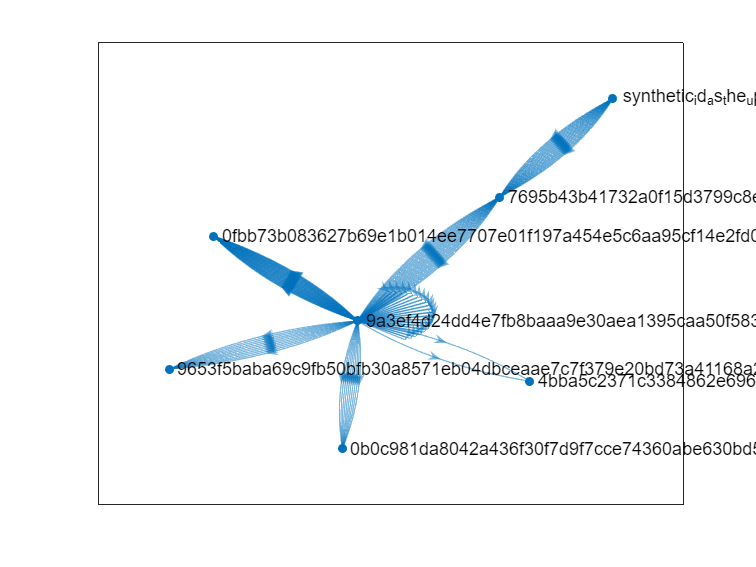

val = prev_svc_data.Value{1,1};
plot(val.graph{:});

val.traces{:}

ans = 128×9 table
      Nr                   trace_id                timestamp      rpc_id                                  upstream_ms                                rpc_type                              downstream_ms                                                           interface                                 response_time
    _______    ________________________________    _________    ___________    __________________________________________________________________    ________    __________________________________________________________________    __________________________________________________________________    _____________

    5028166    "0b51060215919238027621000ef5f

### Port dataformat

From MapReduce KeyValueDatastore output to serial processing

(we leave the map-reduce environment and process classically)

services = readall(services_ds);

### Extract 30 apps

We inspect the found service graphs for similarity and cluster them into 30 'apps'.

[services_a] = app_cluster(services,0.2,30);

### App Graphs

Construct graphs for each app (cluster)

[apps] = app_graphs(services_a);

Generating graph for app 1
Generating graph for app 2
Generating graph for app 3
Generating graph for app 4
Generating graph for app 5
Generating graph for app 6
Generating graph for app 7
Generating graph for app 8
Generating graph for app 9
Generating graph for app 10
Generating graph for app 11
Generating graph for app 12
Generating graph for app 13
Generating graph for app 14
Generating graph for app 15
Generating graph for app 16
Generating graph for app 17
Generating graph for app 18
Generating graph for app 19
Generating graph for app 20
Generating graph for app 21
Generating graph for app 22
Generating graph for app 23
Generating graph for app 24
Generating graph for app 25
Generating graph for app 26
Generating graph for app 27
Generating graph for app 28
Generating graph for app 29
Generating graph for app 30


### MS by service (interface)

Create a list of services (interfaces) involved AND the microservices in use for those.

This data can be used to extract more traces from other csv files and to extract MS resource useage from the given dataset.

svc_meta = vertcat(services.Value{:,1});
function [involved_ms] = getInvolvedMs(row, upstream_is_user_id)
    % Return edges of the graph in a cell
    ms_including_synthetic = unique([row.upstream_ms; row.downstream_ms]);
    involved_ms = {ms_including_synthetic(strcmp(ms_including_synthetic, upstream_is_user_id) == 0)};
end

[upstream_is_user_id] = constants();
fBound = @(row)getInvolvedMs(row, upstream_is_user_id);
involved_ms = rowfun(fBound, ...
                           svc_meta, ...
                           "InputVariables","traces", ...
                           "ExtractCellContents",true);
ms_by_svc = table(services.Key, involved_ms{:,:})

ms_by_svc = 483×2 table
                                    Var1                                         Var2     
    ____________________________________________________________________    ______________

    {'6e3e36ad3820a2f4dc15760c74fcd53448db5091fa1cdcf4590d0a394c03b383'}    {  8×1 string}
    {'073ee5560878adb7ebd7b3dc3a7eeb7578032a6636fe0c7334ce97467b0ea78e'}    { 76×1 string}
    {'3b6a8192293afd88f8be62fe7ab42b2e2f1941838630cc2806fb1d0ebdfbc34d'}    { 21×1 string}
    {'155adadf533deb1e5b50c9f3e9c2e129ff69e8beda6847e4e3b485b07b9b1579'}    { 16×1 string}
    {'0ab4dfdeb6ac1eec0a3c16701058bbfebe466fe1cc96724a899110f63f72f4c4'}    { 40×1 string}
    {'c680548e201164a0ddaefebbdc8e69054dcc701b7859807a8ca619ac1b9dc1d5'}    { 25×1 string}
    {'c9de6f2895d67dc65b03c7f1cdbc0897fff1b98e833d729f3f917790549d8496'}    {123×1 string}
    {'54385f8657c62040138443fd13c633311a88886ca231eb9fca1d3edc0cc9894e'}    {  9×1 strin

save(output_dir_root+"/ms_by_interfaces.mat", "ms_by_svc");

### Create directory structure

To be filled with app graphs and traces (for both sequential and parallel)

for i=1:height(apps)
    mkdir(app_trace_dir(output_dir_sequential,i));
    mkdir(app_trace_dir(output_dir_parallel,i));
end

### .gitignores

% add .gitignores for convenience so results can be moved around freely
fid = fopen(output_dir_root+"/.gitignore",'w');
fprintf(fid,"*");
fclose(fid);

### Create mubench app graphs

Creates the service_graph.json files

create_app_graphs_for_mbench(apps);

### Create mubench traces sequential

Creates the trace_XXXXX.json files for the sequential branch

tic
mb_trace_stats_seq = create_app_traces_for_mbench(apps,false);

toc

Elapsed time is 213.403933 seconds.


### Create mubench traces parallel

Creates the trace_XXXXX.json files for the parallel branch

mb_trace_stats_par = create_app_traces_for_mbench(apps,true);